%define grid spacing for vector fields
vgrid = 1.0/3.0;
%define grid spacing for scalar fields
sgrid = 0.05;

%Define function of interest as anonymous functions
%leave only 1 function uncommented

%Vector field of interest, with parameter
%Note: we define the vector field directly, rather than as a gradient
a = 1

a = 1

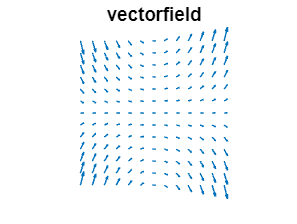

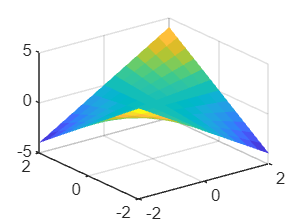

v1 = @(x,y) 1;
v2 = @(x,y) a*x*y;

%Define meshes for 2d scalar and vector fields
[Xs,Ys] = meshgrid(-2:sgrid:2,-2:sgrid:2);
[Xv,Yv] = meshgrid(-2:vgrid:2,-2:vgrid:2);

%arrayfun applies the anonymous function to matrices
%DX is v1, DY is v2. Use the vector grid.
DX = arrayfun(v1,Xv,Yv);
DY = arrayfun(v2,Xv,Yv);

%Plotting vector field
quiver(Xv,Yv,DX,DY)
title("vectorfield")
set(gca,'xtick',[]);
set(gca,'ytick',[]);
set(gca,'Box','off')
axis off
axis equal